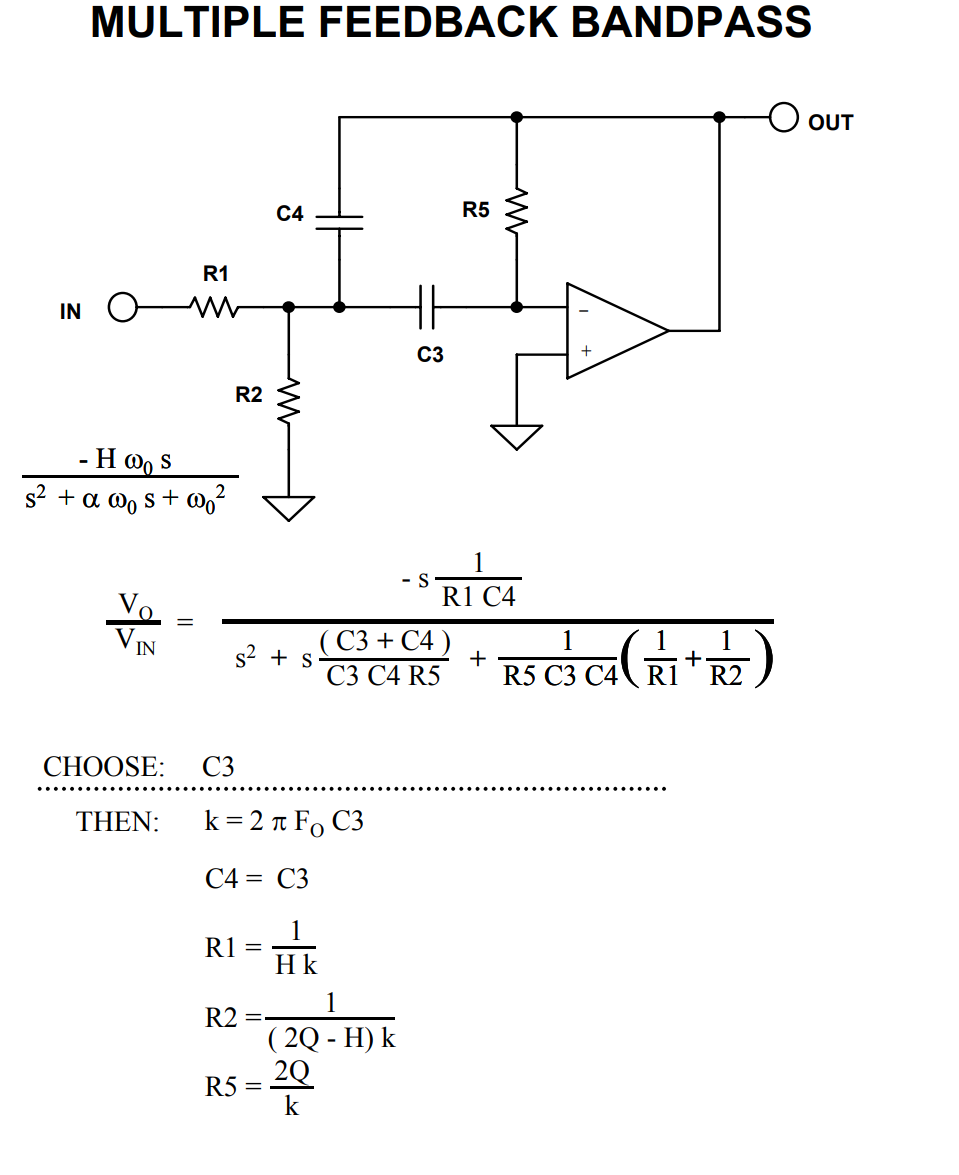

% Define the tf as anon
MFB = @(s, C, R1, R2, R3) ((s./(R1*C))./(s.^2 + s.*((2*C)/(R3*C^2))  + (1/(R3*C^2)*((R1+R2)/(R1*R2)))));

%Define anon to convert to dB
lin2dB = @(c) 10*log10(abs(c));

% Define cascaded 4th order circuit
MFB_4th_order = @(s, C, R1, R2, R3) MFB(s, C, R1, R2, R3).*MFB(s, C, R1, R2, R3);
% Add noninverting amplfier gain
H4 = @(C, R1, R2, R3, Rb) simplify((1+(Rb/Rcut))*MFB_4th_order(s, C, R1, R2, R3));


% Interactive sliders
fc = 110;
bw = 180;
scale = 1;


% Define standard cap
Cs = 10e-9/scale;
% Compute MFB values
[R1, R2, R3] = computeMFB(fc, bw, Cs, 1)

R1 = 1.4469e+05

R2 = 6.5109e+05

R3 = 1.7684e+05

R1 = R1*scale; R2 = R2*scale; R3 = R3*scale'

R3 = 1.7684e+05

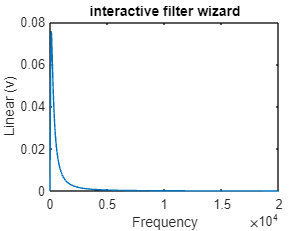


% Define the freq domain
freqs = linspace(0, 20e3, 40e3);
s_domain = 2*pi*freqs;
% compute freq response
tf_resp = (MFB_4th_order(s_domain, Cs, R1, R2, R3));


plot(freqs, tf_resp)

title('interactive filter wizard')
xlabel('Frequency')
ylabel('Linear (v)')

appendix

% Compute Multipule Feedback Bandpass

function [ R1, R2, R3] = computeMFB(fc, bw, C, H);
scale = 1000;

% Compute quality
Q = fc/bw;
% define wavenum
k = 2*pi*fc*C;
% compute resistor values
R1 = 1/(H*k);
R2 = 1/(k*(2*Q - H));
R3 = 2*Q/k;

end


function [Cs, Rq, Rs] = computeVBT(fc, bw);
% Define an impedance scale
z_scale = 10e3;
% Set the standard resistor equal to scale
Rs = z_scale;
% Compute the Angular frequency 
W = 2*pi*fc;
%Compute Quality of osccilation
Q = z_scale*fc/bw
Rq = Q
% Compute capacitor value by applying z scale and frequency scale
Cs = 1/(z_scale*W)

end